# 1. 建立桥梁模型

% 协作体系模型
b = CableStayedSuspension_Bridge;
b.build;

Is building a Cable-Stayed Suspension Bridge...


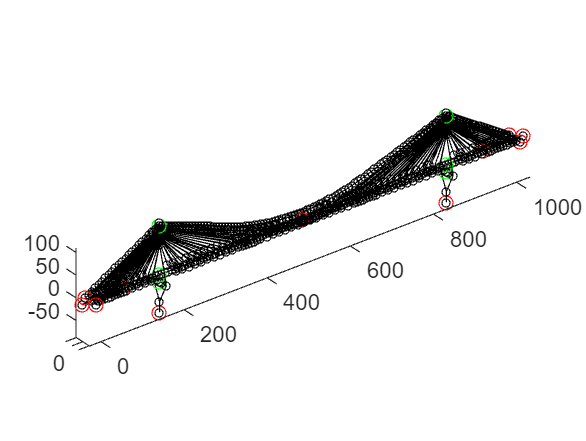

ans =   Figure (2) - 属性:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [440 338 560 420]
       Units: 'pixels'

  显示 所有属性


b.plot

output_method = OutputToAnsys(b,"JobName",'TotalModel',...
    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
    'WorkPath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\CS_Bridge',...
    'MacFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\CS_Bridge\main.mac',...
    'ResultFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\CS_Bridge\result.out');
b.OutputMethod = output_method;

# 2. 计算无索模型的最小弯曲应变能，获得最优设计竖向力

% 无索模型
bridge_state = NoCable_Bridge(b);
bridge_state.build

Is building a Brigde without Cable System...


output_method = OutputToAnsys(bridge_state,"JobName",'NonCableModel',...
    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
    'WorkPath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\NC_Bridge',...
    'MacFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\NC_Bridge\main.mac',...
    'ResultFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\NC_Bridge\result.out');
bridge_state.OutputMethod = output_method;
[FEModel,isEquationCompleted] = bridge_state.getFiniteElementModel;

Is getting Finite Element Model from ANSYS...



% 优化弯曲应变能
bridge_state.optimBendingStrainEnergy('MaxIter',25,'DiffMinChange',1e4);

Is optimizing the Bending Strain Energy...
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      79    1.427470e+08    0.000e+00    2.034e+01
    1     158    1.427399e+08    0.000e+00    2.034e+01    8.460e+01
    2     237    1.427041e+08    0.000e+00    2.034e+01    4.230e+02
    3     316    1.425254e+08    0.000e+00    2.033e+01    2.115e+03
    4     395    1.416340e+08    0.000e+00    2.026e+01    1.057e+04
    5     474    1.372382e+08    0.000e+00    1.992e+01    5.265e+04
    6     553    1.167441e+08    0.000e+00    1.823e+01    2.587e+05
    7     632    4.649625e+07    0.000e+00    1.053e+01    1.182e+06
    8     711    1.261748e+07    0.000e+00    2.099e+00    1.571e+06
    9     790    1.261739e+07    0.000e+00    2.099e+00    1.019e+01
   10     869    1.261692e+07    0.000e+00    2.099e+00    4.841e+01
   11     948    1.261461e+07    0.000e+00    2.099e+00    2.420e+02
   1

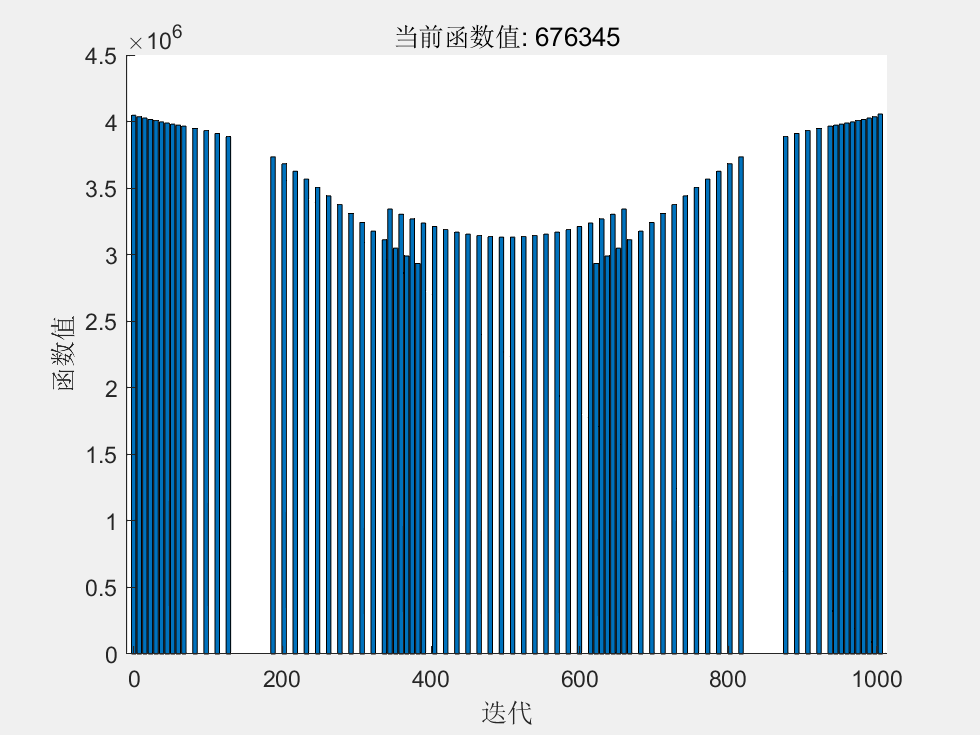


% 结果呈现
Map_Pz = bridge_state.Result_Iteration.Iter_Pz;
max_iter = bridge_state.Iter_Optimization;
Pz_final = Map_Pz(max_iter);
X = bridge_state.OriginalBridge.getSortedGirderPointXCoord([bridge_state.OriginalBridge.findStructureByClass('Hanger'),bridge_state.OriginalBridge.findStructureByClass('StayedCable')]);
bar(X,Pz_final)

# 3. 根据最优设计竖向力，导出到ANSYS中，查看计算效果

% 无索模型的ANSYS结果
output_method = OutputToAnsys(bridge_state,"JobName",'NonCableModel',...
    'AnsysPath','C:\Program Files\ANSYS Inc\ANSYS Student\v232\ansys\bin\winx64\MAPDL.exe',...
    'WorkPath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\Optimed_NC_Bridge',...
    'MacFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\Optimed_NC_Bridge\main.mac',...
    'ResultFilePath','C:\Users\11440\Desktop\usage\CableSuspensionBridge\Optimed_NC_Bridge\result.out');
bridge_state.OutputMethod = output_method;
bridge_state.output

% 协作体系模型的ANSYS结果

% 为

# 4. 如果与实际不相符，则检查模型，特别是其中的实常数

# 5. MATLAB控制ANSYS进行优化，控制初应变，使得达到最优设计竖向力